plt1 = csvread("AK_Exp3_Plot1_Small_Amplitude.csv");
startpoint = 1000;
endpoint = 4000;
time=plt1(startpoint:endpoint,1,:);
ch1=plt1(startpoint:endpoint,2,:);
ch2=plt1(startpoint:endpoint,3,:);
time = time + 0.001851551083806;

% Plot input and output waveforms
figure;
%semilogy(time,ch2-min(ch2),'b')
[first,last,mdn,bdn,n]= linefit(time,log(ch2 - min(ch2)),0.1)

first = 861

last = 965

mdn = 3.5867e+04

bdn = -24.0359

n = 105

[first,last,mup,bup,n]= linefit(time,log(max(ch2) - ch2),0.1)

first = 2451

last = 2520

mup = 5.0302e+04

bup = -82.3178

n = 70


plot(time,ch1); hold on
plot(time,ch2)
plot(time, max(ch2)-exp(mup*time+bup))
plot(time,exp(mdn*time+bdn)+min(ch2)); 
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Input and Output Scopetraces with extracted time constants');
legend('Input (ch1)', 'Output (ch2)','Up-going Time Constant','Down-going Time Constant');
ylim([1.35, 1.73])
grid on;
fprintf('Up-going time constant: %f\n', 1/mup)

Up-going time constant: 0.000020


fprintf('Down-going time constant: %f\n', 1/mdn)

Down-going time constant: 0.000028


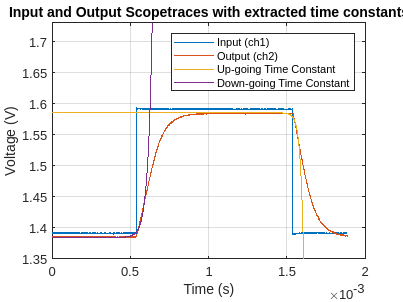

print("-depsc","experiment3_1.eps")

function [first, last, mmax, bmax, Nmax]=linefit(x, y, epsilon)

first=0;
last=0;
mmax=0;
bmax=0;
Nmax=0;

i=1;
while i<length(x),
    R2=1;
    N=1;
    sumX=x(i);
    sumX2=x(i)*x(i);
    sumY=y(i);
    sumY2=y(i)*y(i);
    sumXY=x(i)*y(i);
    j=i;
    while (j<length(x)) & (R2>1-epsilon),
        j=j+1;
        N=N+1;
        sumX=sumX+x(j);
        sumX2=sumX2+x(j)*x(j);
        sumY=sumY+y(j);
        sumY2=sumY2+y(j)*y(j);
        sumXY=sumXY+x(j)*y(j);
        SXX=sumX2-sumX*sumX/N;
        SYY=sumY2-sumY*sumY/N;
        SXY=sumXY-sumX*sumY/N;
        m=SXY/SXX;
        b=(sumY-m*sumX)/N;
        R2=SXY*SXY/(SXX*SYY);
    end
    if ((N>10) & (abs(m)>abs(mmax))),
        first=i;
        last=j;
        mmax=m;
        bmax=b;
        Nmax=N;
    end
    i=j;
end
end